Question 1a

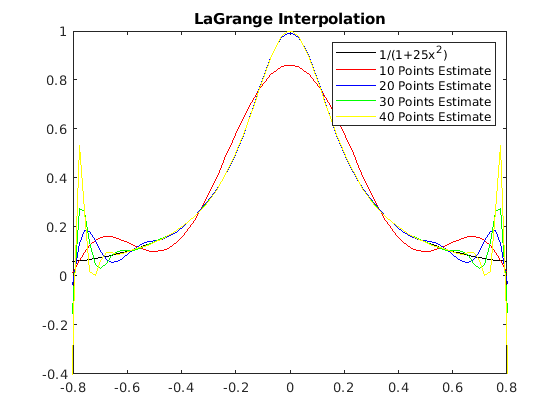

p = @(x) 1./(1+25*x.^2);
X = linspace(-1, 1, 100);
x10 = linspace(-1, 1, 10);
x20 = linspace(-1, 1, 20);
x30 = linspace(-1, 1, 30);
x40 = linspace(-1, 1, 40);
y10 = linterp(x10, p(x10), X);
y20 = linterp(x20, p(x20), X);
y30 = linterp(x30, p(x30), X);
y40 = linterp(x40, p(x40), X);
plot(X, p(X), 'k-', X, y10, 'r-', X, y20, 'b-', X, y30, 'g-', X, y40, 'y-');
title("LaGrange Interpolation");
legend("1/(1+25x^2)","10 Points Estimate", "20 Points Estimate", "30 Points Estimate", "40 Points Estimate")
xlim([-0.8, 0.8])

    Increasing the number of sample points does give a better LOCAL approximation, but increases error around the ends as it tends to follow a much stronger sinusoidal wave.

Question 1b

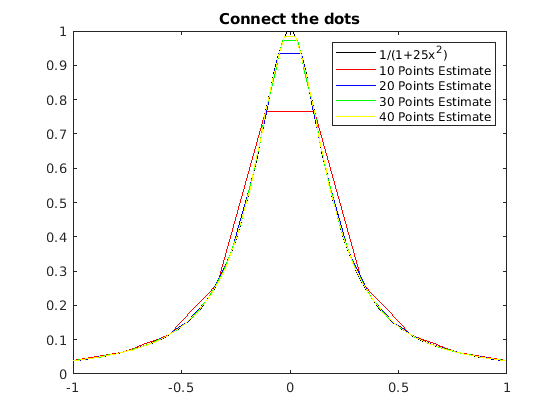

[x10, y10] = plinterp(x10, p(x10));
[x20, y20] = plinterp(x20, p(x20));
[x30, y30] = plinterp(x30, p(x30));
[x40, y40] = plinterp(x40, p(x40));
plot(X, p(X), 'k-', x10, y10, 'r-', x20, y20, 'b-', x30, y30, 'g-', x40, y40, 'y-');
title("Connect the dots");;
legend("1/(1+25x^2)","10 Points Estimate", "20 Points Estimate", "30 Points Estimate", "40 Points Estimate")

Yes it seems like these are better approximations than the previous implementation.

Question 1c

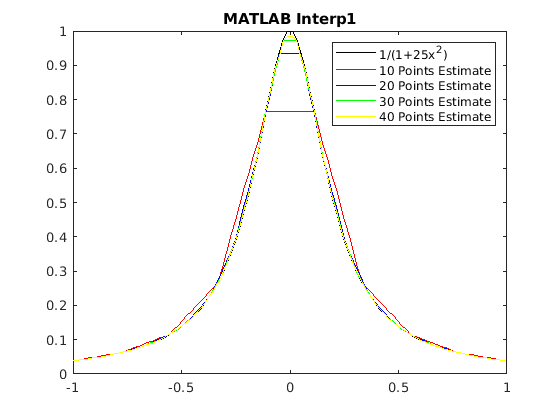

x10 = linspace(-1, 1, 10);
x20 = linspace(-1, 1, 20);
x30 = linspace(-1, 1, 30);
x40 = linspace(-1, 1, 40);
y10 = interp1(x10, p(x10), X);
y20 = interp1(x20, p(x20), X);
y30 = interp1(x30, p(x30), X);
y40 = interp1(x40, p(x40), X);
plot(X, p(X), 'k-', X, y10, 'r-', X, y20, 'b-', X, y30, 'g-', X, y40, 'y-');
title("MATLAB Interp1");
legend("1/(1+25x^2)","10 Points Estimate", "20 Points Estimate", "30 Points Estimate", "40 Points Estimate")

Question 1d

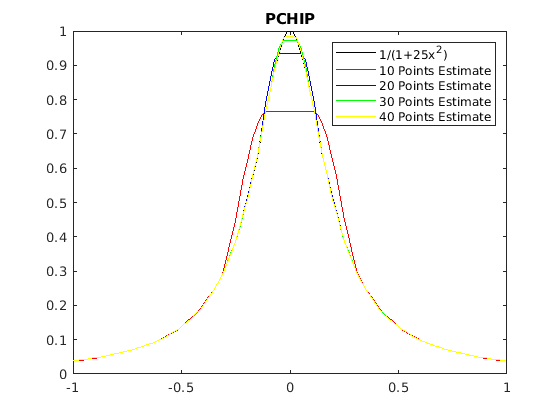

y10 = pchip(x10, p(x10), X);
y20 = pchip(x20, p(x20), X);
y30 = pchip(x30, p(x30), X);
y40 = pchip(x40, p(x40), X);
plot(X, p(X), 'k-', X, y10, 'r-', X, y20, 'b-', X, y30, 'g-', X, y40, 'y-');
title("PCHIP");
legend("1/(1+25x^2)","10 Points Estimate", "20 Points Estimate", "30 Points Estimate", "40 Points Estimate")

Although it looks smoother, it does seem to deviate more in some lines, such as 10 points, it deviates more as the slope increasaes or decreases dramatically.

function y = linterp(X, Y, x)
    y = 0;
    for i = 1:numel(X)
        yy = Y(i);
        for j = 1:numel(X)
            if i ~= j
                yy = yy .* (x - X(j)) / (X(i) - X(j));
            end
        end
        y = y + yy;
    end
end

function [bigX, bigY] = plinterp(X, Y)
    bigX = [];
    bigY = [];
    for i = 1:numel(X)-1
        xx = linspace(X(i), X(i+1), 5);
        yy = linterp([X(i) X(i+1)], [Y(i) Y(i+1)], xx);
        bigX = [bigX xx];
        bigY = [bigY yy];
    end
end